*****This file is for testing each filter**

clear
clc
addpath("srcs\all_func\")

Import

imgs = imageDatastore("srcs/imgs", "IncludeSubfolders", false);
n = numel(imgs.Files);

Apply Filter

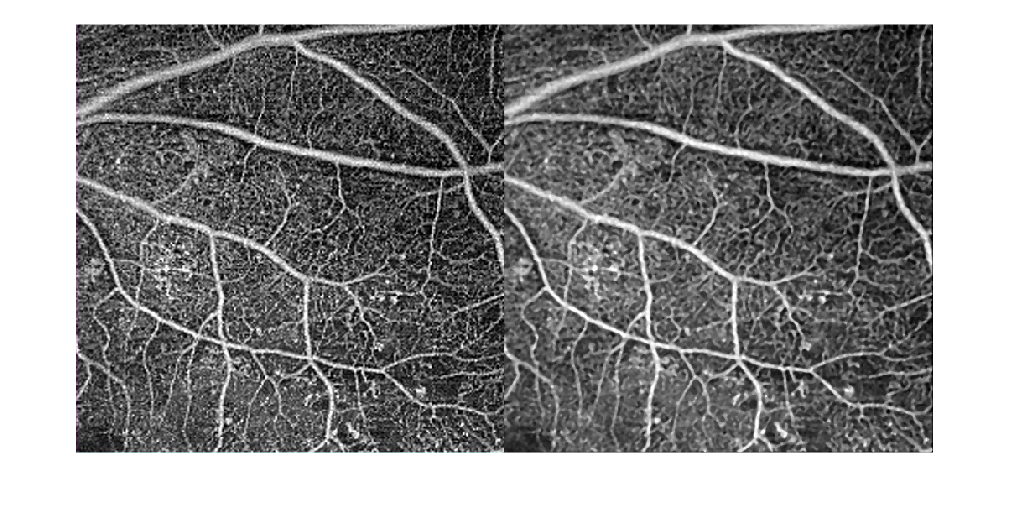

%test_img = imgs.read;
test_img = readimage(imgs, 1);
test_img_bw = imbinarize(AllFilters.imagePrepare(test_img), 'adaptive');
res = AllFilters.medFilter(test_img);
%res = AllFilters.imClose(res);
%res = imbinarize(res,"adaptive");

%Compare with original
imshowpair(test_img, res, 'montage')

Comparision between filter

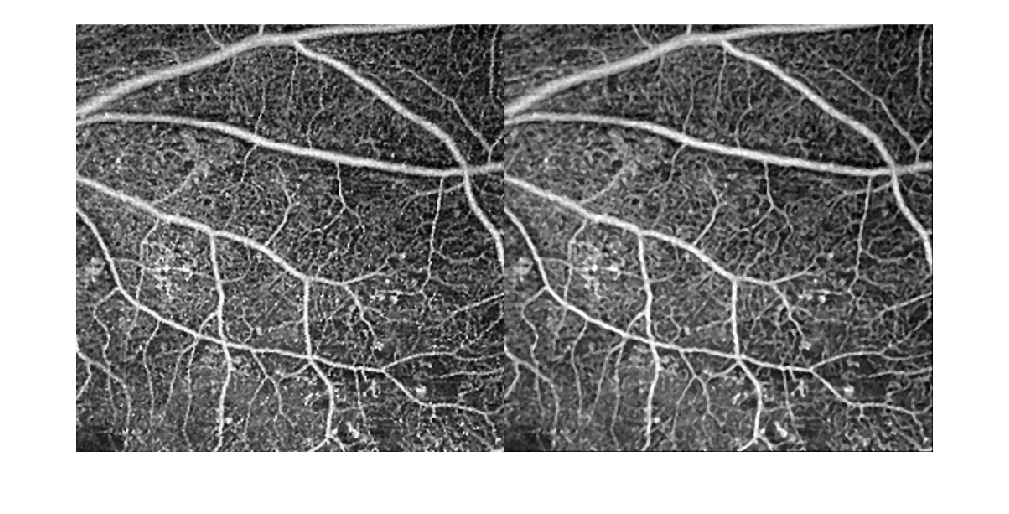

org = @(img) imbinarize(img, 'adaptive');
fclose = @AllFilters.imClose;
func1 = @AllFilters.wienerFilter;
func2 = @AllFilters.medFilter;
fcloseW1 = @(img) fclose(func1(img));
fcloseW2 =  @(img) fclose(func2(img));

compare_filt(func1, func2, test_img);

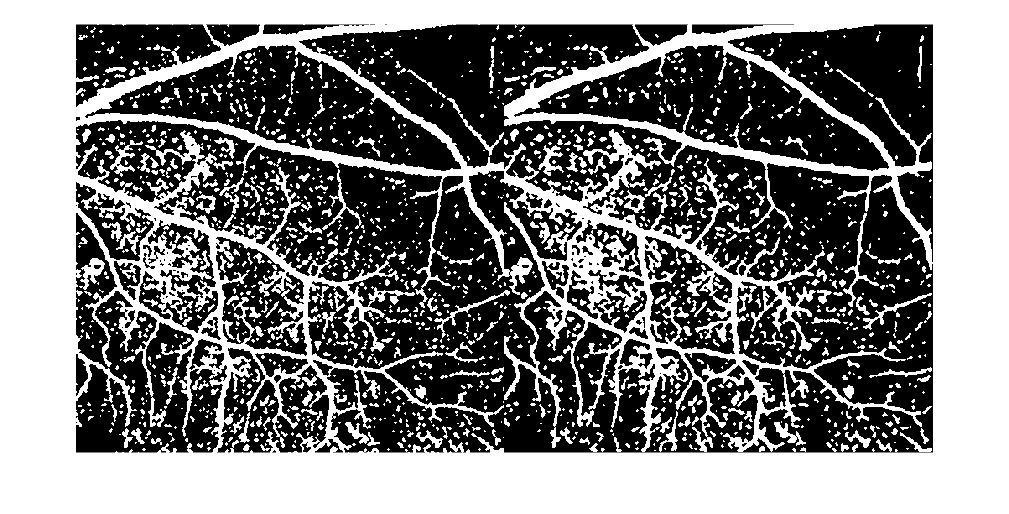

compare_filt(fcloseW1, fcloseW2, test_img);

%imshowpair(double(org(test_img)), fcloseW1(test_img), 'diff');

Calculate signal to noise ratio of each filtered image lower = better

filtNames = categorical({'Gauss', 'Bilat', 'Wiener'});
filtNames = reordercats(filtNames, {'Gauss', 'Bilat', 'Wiener'})

filtNames = 1×3 categorical array
     Gauss      Bilat      Wiener 


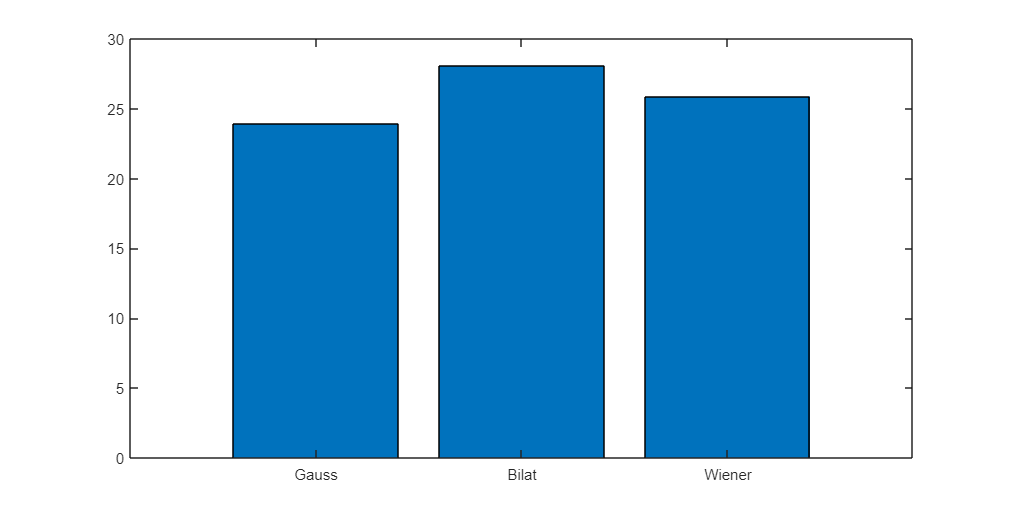

i = {AllFilters.gaussFilter(test_img)};
i{2} = AllFilters.bilateralFilter(test_img);
i{3} = AllFilters.wienerFilter(test_img);
n = numel(i);

for j = [1:n]
    psnrVal(j) = psnr(i{j}, rgb2gray(test_img));
end
bar(filtNames, psnrVal);

Image Segmentation

%test_img = AllFilters.imagePrepare(test_img);
[pik_im, pik_g2, pik_sdMap, pik_vLog] = vessel_seg(test_img, 4);

Error using imadjust>parseInputs
Specified syntax IMADJUST(I) is only supported for 2-D grayscale images. Additional input arguments are required for use with RGB images.

Error in imadjust (line 105)
    parseInputs(varargin{:});

Error in vessel_seg (line 17)
    g2 = imadjust(g2);

L = imsegkmeans(test_img, 2);
C = labeloverlay(test_img, L);
imshow(pik_im)